clf
clear
plot_pdetection = 1;
plot_falsepositive = 0;
plot_title = "P(false positive) noisy velocity, similar slope attack at Various Target Ranges";
MAX_BIN = 30;
BIN_SIZE = 5;
TOTAL_FRAMES = 2000;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/csvs_to_plot/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\csvs_to_plot\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/csvs_to_plot/";
base_path = david_file_path;
% csvs = ["4GHz_no_attack.csv", "4GHz_sim_slope_noisy_vel.csv",...
%     "4GHz_target.csv","4GHz_sim_slope_sim_vel.csv"];
% csvs = ["20MHz_sim_slope_noisy_vel.csv", "100MHz_sim_slope_noisy_vel.csv",...
%     "1GHz_sim_slope_noisy_vel.csv","4GHz_sim_slope_noisy_vel.csv"];
csvs = ["20MHz_no_attack.csv"];
colors_list = ["b", "g", "c", "m", "y", "k", "r"];
color_idx = 1;

for csv = csvs
    table_data = readtable(base_path + csv);
    range_col = table_data{:, 1};
    bin_classification = cast(range_col/BIN_SIZE, "int16")';
    histogram_vals = zeros(MAX_BIN,3);
    for bin_num = 1:MAX_BIN
        histogram_vals(bin_num, 1) = bin_num;
        count = 0;
        detected = 0;
        false_pos = 0;
        for frame = 1: TOTAL_FRAMES
            if (bin_classification(frame) == bin_num)
                count = count + 1;
                if table_data{frame, 3}
                    detected = detected + 1;
                end
                if table_data{frame, 8}
                    false_pos = false_pos + 1;
                end
            end
        end
        if (count ~= 0)
            histogram_vals(bin_num, 2) = detected/count;
            histogram_vals(bin_num, 3) = false_pos/count;
        end
    end

    if (plot_pdetection)
        hold on
        plot(histogram_vals(:,1)*BIN_SIZE, histogram_vals(:,2), colors_list(color_idx));
        color_idx = color_idx +1;
        hold off
    end

    if (plot_falsepositive)
        hold on
        plot(histogram_vals(:,1)*BIN_SIZE, histogram_vals(:,3), colors_list(color_idx));
        color_idx = color_idx + 1;
        hold off
    end
end

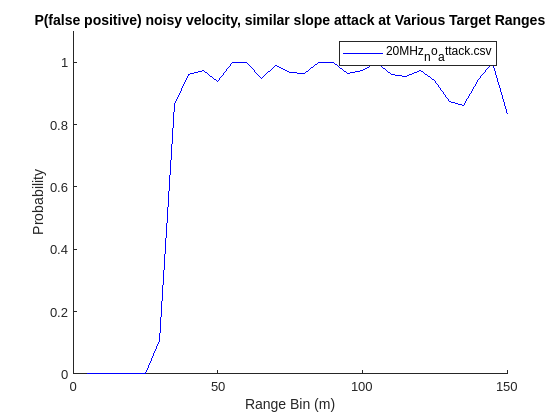

ylabel("Probability")
ylim([0,1.1])
legend(csvs)
xlabel("Range Bin (m)")
title(plot_title)
print('-r300',"generated_plots/combined_result_plot",'-dsvg')
print('-r300',"generated_plots/combined_result_plot",'-dpng')